addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))

%Operations
ops0.fig                       = 1;
ops0.saveData                  = 1;
ops0.loadSyntheticData         = 1;

% Load Dataset
make_db
if ops0.loadSyntheticData
    setupSyntheticDataParameters
end

% Save details
saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


i = length(sdcp);
if ops0.loadSyntheticData
        load([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' num2str(sdcp(i).eventAmplificationFactor) ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end
trialDetails = getTrialDetails(db);

Getting trial details ...
... done!



nCells = size(myData.dfbf_2D, 1);
nFrames = size(myData.dfbf_2D, 2);

%Remember to transpose the 2D data to rows - allFrames (observations), and columns - Cells (variables)
X = (myData.dfbf_2D)';

## PCA Using MATLAB Functions

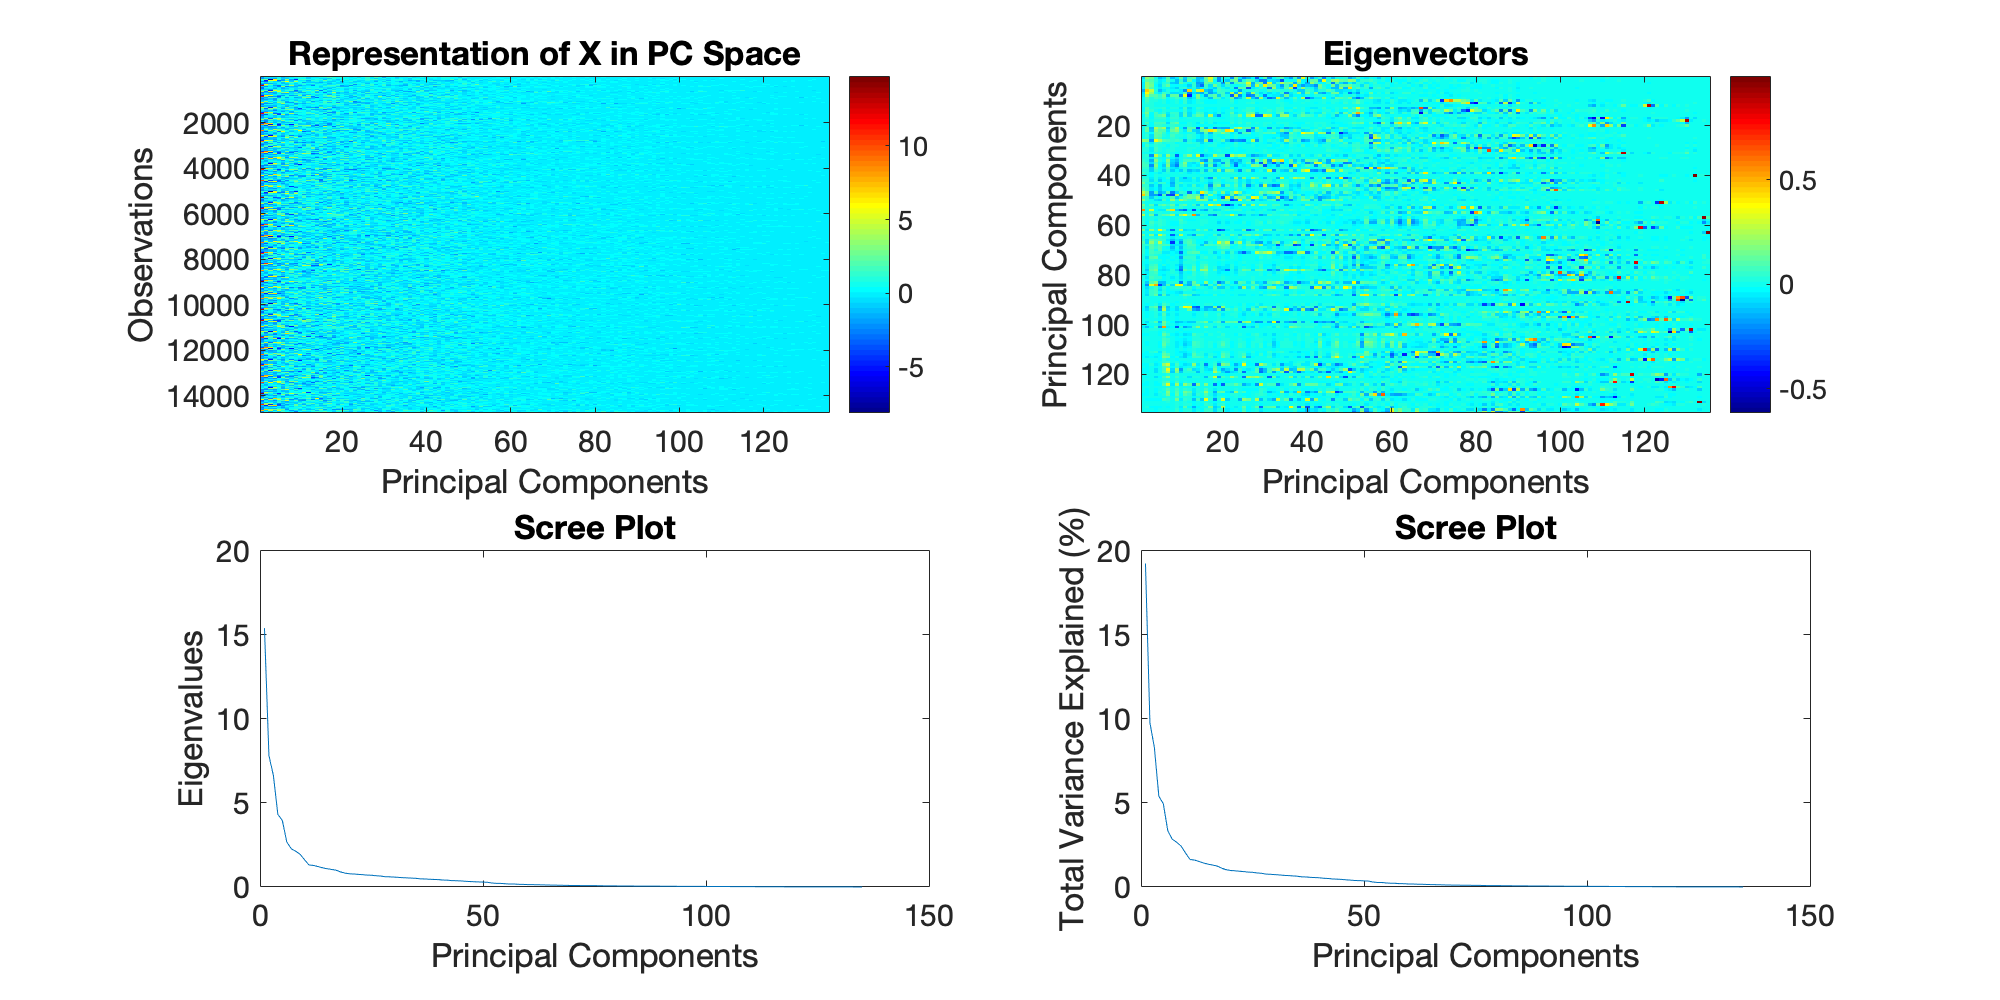

%[coeff, score, latent, tsquared, explained, mu] = pca(X, 'NumComponents', 5);
[coeff, score, latent, tsquared, explained, mu] = pca(X);

if ops0.fig
    fig5 = figure(5);
    set(fig5, 'Position', [300, 300, 1000, 500])
    subplot(2, 2, 1)
    imagesc(score)
    colorbar
    colormap('jet')
    title('Representation of X in PC Space', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 2)
    imagesc(coeff)
    colorbar
    colormap('jet')
    title('Eigenvectors', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 3)
    plot(latent)
    title('Scree Plot', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Eigenvalues', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 4)
    plot(explained)
    title('Scree Plot', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Principal Components', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Total Variance Explained (%)', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
end

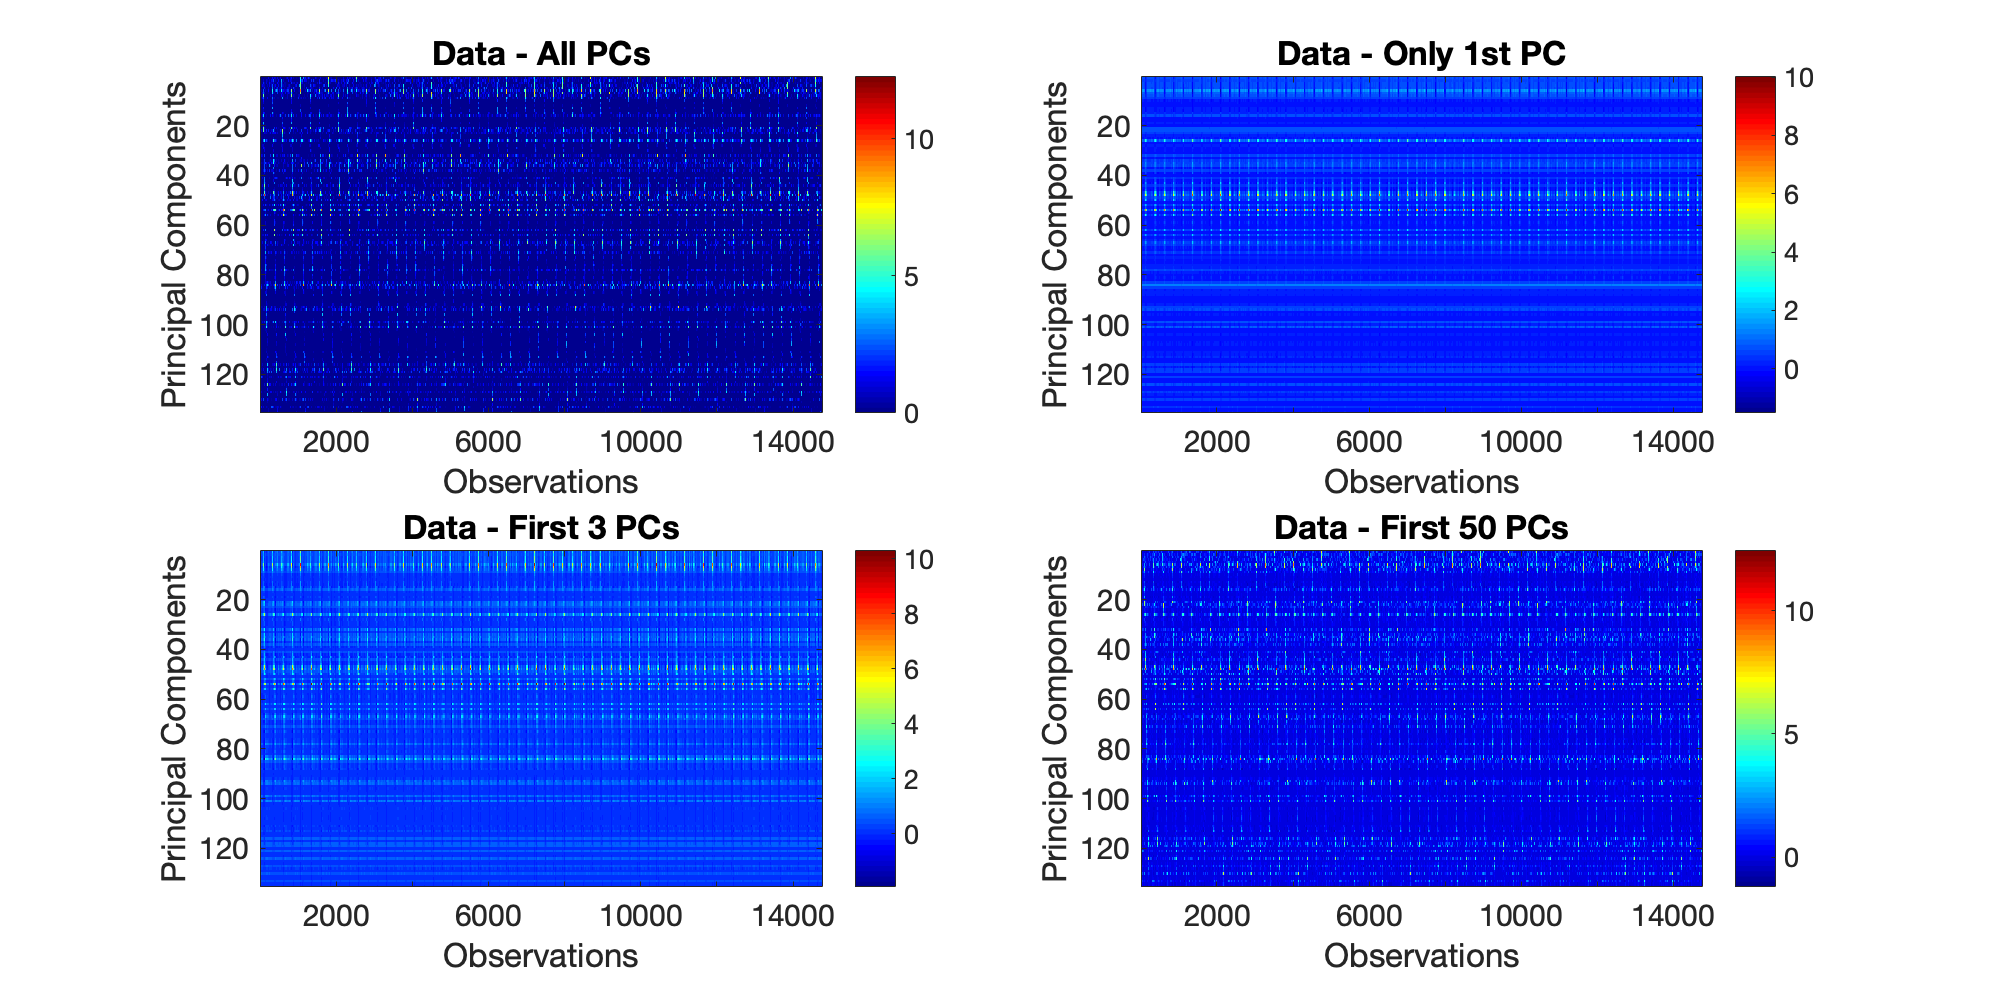

if ops0.fig
    fig6 = figure(6);
    set(fig6, 'Position', [300, 300, 1000, 500])
    subplot(2, 2, 1)
    imagesc(((score * coeff') + mu)')
    colorbar
    colormap('jet')
    title('Data - All PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Cells', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 2)
    imagesc(((score(:,1) * coeff(:, 1)') + mu)')
    colorbar
    colormap('jet')
    title('Data - Only 1st PC', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Cells', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 3)
    imagesc(((score(:,1:3) * coeff(:, 1:3)') + mu)')
    colorbar
    colormap('jet')
    title('Data - First 3 PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Cells', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
    
    subplot(2, 2, 4)
    imagesc(((score(:,1:50) * coeff(:, 1:50)') + mu)')
    colorbar
    colormap('jet')
    title('Data - First 50 PCs', ...
        'FontSize', 15, ...
        'FontWeight','bold')
    xlabel('Observations', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    ylabel('Cells', ...
        'FontSize', 15, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', 15)
end